[m, fs] = audioread('MATLAB.mp3');
m = m(:,1);
duration_sec = 3;
samples = min(length(m), fs*duration_sec);
m = m(1:samples);
t = (0:length(m)-1)'/fs;

fc = 5000;
mu = 0.8;
c = cos(2*pi*fc*t);

dsb_am = (1 + mu * m) .* c;
dsb_sc = m .* c;
m_analytic = hilbert(m);
ssb_sc = real(m_analytic .* exp(1j*2*pi*fc*t));

m_dsb_am = abs(hilbert(dsb_am)) - 1;
m_dsb_sc = 2 * dsb_sc .* c;
m_dsb_sc = lowpass(m_dsb_sc, 4000, fs);
m_ssb_sc = 2 * ssb_sc .* c;
m_ssb_sc = lowpass(m_ssb_sc, 4000, fs);

m = m / max(abs(m));
dsb_am = dsb_am / max(abs(dsb_am));
dsb_sc = dsb_sc / max(abs(dsb_sc));
ssb_sc = ssb_sc / max(abs(ssb_sc));
m_dsb_am = m_dsb_am / max(abs(m_dsb_am));
m_dsb_sc = m_dsb_sc / max(abs(m_dsb_sc));
m_ssb_sc = m_ssb_sc / max(abs(m_ssb_sc));

disp('Playing Original Message...'); sound(m, fs); pause(duration_sec+1);

Playing Original Message...


disp('Playing DSB-AM Modulated...'); sound(dsb_am, fs); pause(duration_sec+1);

Playing DSB-AM Modulated...


disp('Playing DSB-SC Modulated...'); sound(dsb_sc, fs); pause(duration_sec+1);

Playing DSB-SC Modulated...


disp('Playing SSB-SC Modulated...'); sound(ssb_sc, fs); pause(duration_sec+1);

Playing SSB-SC Modulated...


disp('Playing DSB-AM Demodulated...'); sound(m_dsb_am, fs); pause(duration_sec+1);

Playing DSB-AM Demodulated...


disp('Playing DSB-SC Demodulated...'); sound(m_dsb_sc, fs); pause(duration_sec+1);

Playing DSB-SC Demodulated...


disp('Playing SSB-SC Demodulated...'); sound(m_ssb_sc, fs);

Playing SSB-SC Demodulated...


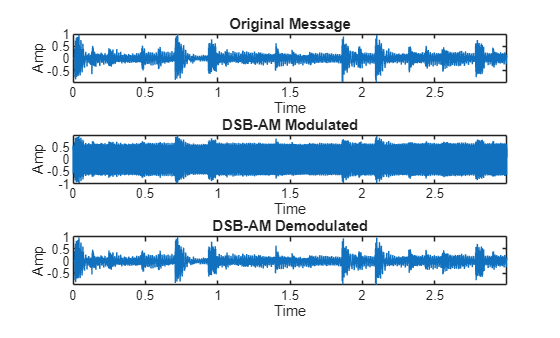


figure;
subplot(3,1,1); plot(t, m); title('Original Message'); xlabel('Time'); ylabel('Amp'); axis tight;
subplot(3,1,2); plot(t, dsb_am); title('DSB-AM Modulated'); xlabel('Time'); ylabel('Amp'); axis tight;
subplot(3,1,3); plot(t, m_dsb_am); title('DSB-AM Demodulated'); xlabel('Time'); ylabel('Amp'); axis tight;

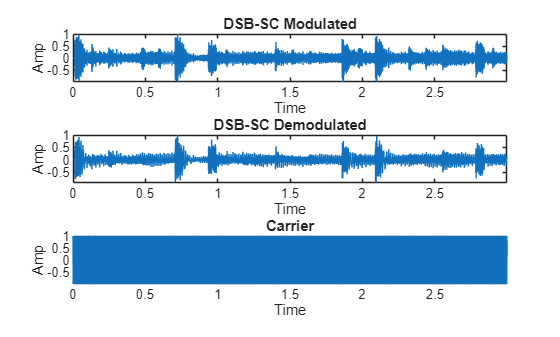


figure;
subplot(3,1,1); plot(t, dsb_sc); title('DSB-SC Modulated'); xlabel('Time'); ylabel('Amp'); axis tight;
subplot(3,1,2); plot(t, m_dsb_sc); title('DSB-SC Demodulated'); xlabel('Time'); ylabel('Amp'); axis tight;
subplot(3,1,3); plot(t, c); title('Carrier'); xlabel('Time'); ylabel('Amp'); axis tight;

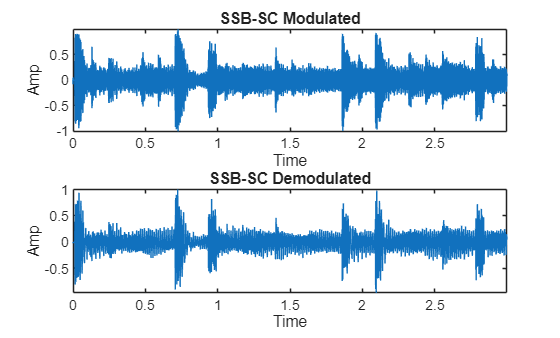


figure;
subplot(2,1,1); plot(t, ssb_sc); title('SSB-SC Modulated'); xlabel('Time'); ylabel('Amp'); axis tight;
subplot(2,1,2); plot(t, m_ssb_sc); title('SSB-SC Demodulated'); xlabel('Time'); ylabel('Amp'); axis tight;

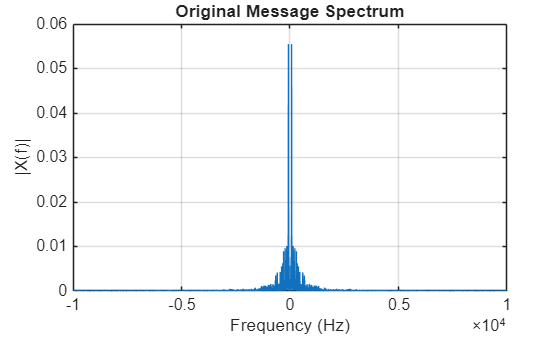


plot_spectrum(m, fs, 'Original Message Spectrum');

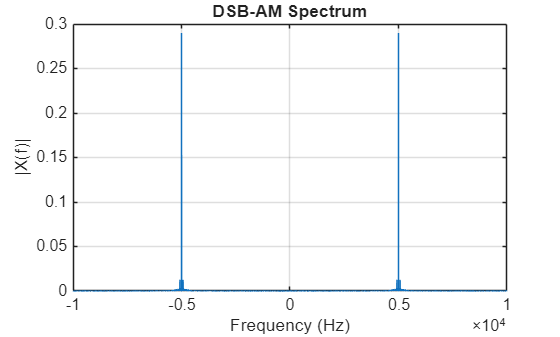

plot_spectrum(dsb_am, fs, 'DSB-AM Spectrum');

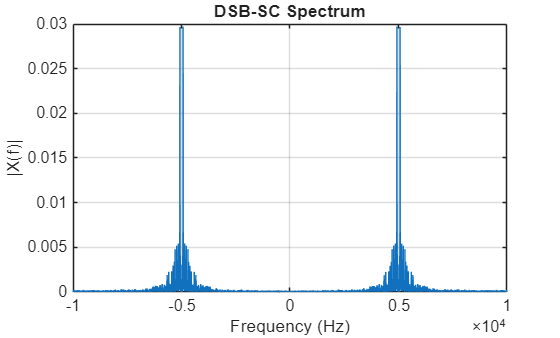

plot_spectrum(dsb_sc, fs, 'DSB-SC Spectrum');

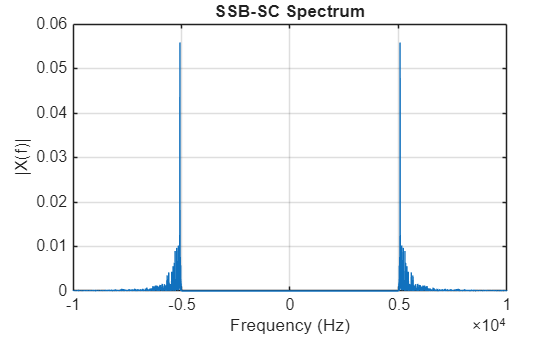

plot_spectrum(ssb_sc, fs, 'SSB-SC Spectrum');


function plot_spectrum(x, fs, title_str)
    N = length(x);
    X = fftshift(abs(fft(x, N))/N);
    f = linspace(-fs/2, fs/2, N);
    figure;
    plot(f, X);
    title(title_str);
    xlabel('Frequency (Hz)');
    ylabel('|X(f)|');
    xlim([-10000 10000]);
    grid on;
end
